# Overview and Motivation

*This example uses a fictional scenario based on a typical engineer's experience for the purpose of demonstration. Any use of names of actual products or firms is entirely coincidental and unintentional. The contents of this example do not constitute a real design.*

*This example was created using MATLAB*®* R2019b.*

*Copyright 2019 The MathWorks, Inc.*

You are an engineer at ***Farnswerth Automotive*** and are on a secret project team developing a single-occupant [Level 5 autonomous vehicle](https://en.wikipedia.org/wiki/Automated_driving_system#Level_5_%E2%80%93_Full_automation), which many call **The Pod**.

Your team, which designs the control system software, is about to complete the "desktop simulation" phase of the project before moving on to the much-anticipated "hardware in the loop" testing phase in the brand new **state-of-the-art** testing facility hidden away from the rest of the company. Everyone is excited!

One of your team's responsibilities is the adaptive cruise control feature, which should set **The Pod** apart from its competition because it will allow multiple Pods to travel within 1 meter of each other at 100 km/h. Your CEO has been posting about this specific feature on social media for months now.

You have been tasked with testing a colleague's design of the Target Speed Selection algorithm, which calculates the vehicle's target speed to be used elsewhere in the adaptive cruise control logic. Your responsibilities are to ensure that the algorithm was implemented correctly according to its requirements and to ensure that it it is completely tested.

In this example workflow, we will use several of the Verification and Validation tools from The MathWorks**®** to accomplish these goals.

We will be using the following MathWorks products:

[**Simulink® Requirements™**](https://www.mathworks.com/products/simulink-requirements.html) to manage requirements in the Simulink environment

[**Simulink® Test™**](https://www.mathworks.com/products/simulink-test.html) to develop, manage, and execute simulation-based tests

[**Simulink® Coverage™**](https://www.mathworks.com/products/simulink-coverage.html) to measure test completeness

[**Simulink® Design Verifier™**](https://www.mathworks.com/products/sldesignverifier.html) to generate test vectors to analyze missing model test coverage

This example assumes that the user has a basic knowledge of [**Simulink®**](https://www.mathworks.com/products/simulink.html) and [**Stateflow®**](https://www.mathworks.com/products/stateflow.html).

# Part 1: Create a Test and Link to Requirements

In Part 1 of the workflow, we will create one test for one requirement. In Part 2, we will run a full test suite, which will test several requirements.

The goals for this part are to learn how to:

- create a test harness

- create a temporal assessment to define pass/fail criteria

- create a test case using the harness and the assessment

- link the test case to the requirement

- execute the created test case to determine whether the test passed

Here are the products we will use in Part 1:

**Simulink® Requirements™ **is used to view and author requirements within Simulink®, as well as to establish traceability between requirements, Simulink® models, and test cases to understand the impact of a change in requirements.

**Simulink® Test™** is used to create, manage, and execute test cases for simulation-based testing in Simulink®. You can use Simulink® Test™ to create test harnesses, create test vectors using a variety of methods such as a test sequence, create test assessments to determine pass/fail criteria, and link test cases to requirements.

We will use other features of Simulink® Test™ in Part 2 of the workflow.

## Step 1: View the Requirement Being Tested

Simulink® Requirements™  includes the Requirements Editor, which is a stand-alone tool (separate from a model) which can be used to import, author, and manage requirements as well as manage requirements traceability. Requirements can be imported from tools such as Microsoft Word, Microsoft Excel, IBM Rational DOORS, ReqIF files, and more.

In this part of the example, we will be working with requirements that have already been imported into Simulink® Requirements™.

Requirements are stored as "requirements sets", which have a file extension of **.slreqx**.

Requirements links are stored as "link sets", which have a file extension of **.slmx**.

Let's open the requirements for the Target Speed Selection algorithm. These are contained in the Cruise Control requirements set.

[**Click here**](matlab:openCruiseControlReqs) to open the Cruise Control requirements in the Requirements Editor, or run the following code (click **Run Section** in the Live Editor toolstrip or type **CTRL + Enter**):

slreq.open('CruiseControl');

The requirement you will be testing has ID #34. It is located in Section 3 of the requirements set.

**"The cruise control system shall transition to disengaged from engaged within 0.25 seconds after a braking event has occurred."**

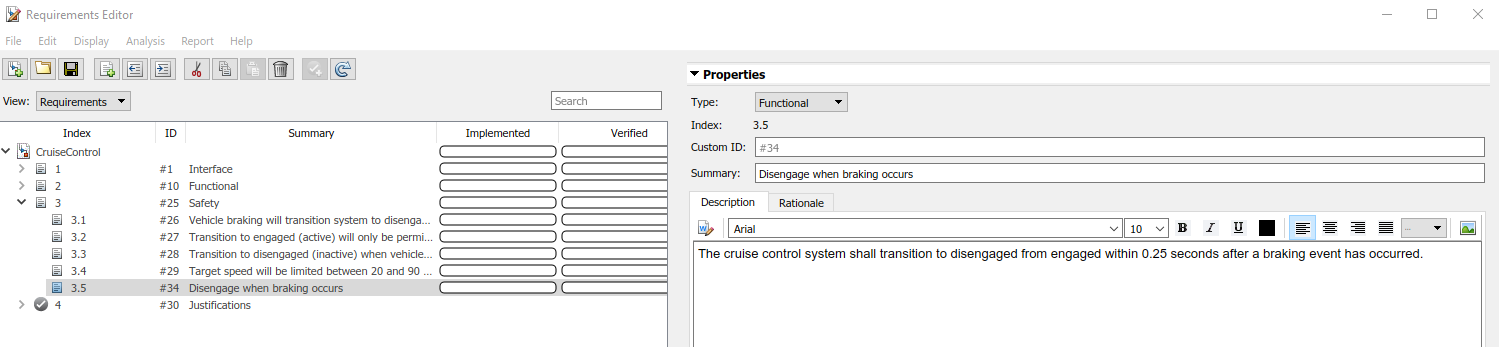

## Step 2: Create a test harness

Test harnesses are independent Simulink® models used to isolate the component under test to verify design models without modifying the design itself. With Simulink® Test™, you can create test harnesses which are automatically associated with a design model. A design model can have several test harnesses.

For this example, we will save the test harness externally from the design model as a separate file. This is done in order to keep track of the testing files separately from the design files. 

Here are the steps to take:

1) Open the Target Speed Selection model by [**clicking here**](matlab:open_system('CruiseControl')), or run the following code (click **Run Section** in the Live Editor toolstrip or type **CTRL + Enter**):

open_system('CruiseControl')

2) Open the Simulink® Test™ app via the Simulink® Toolstrip. The Simulink® Test™ app is available under the APPS tab.

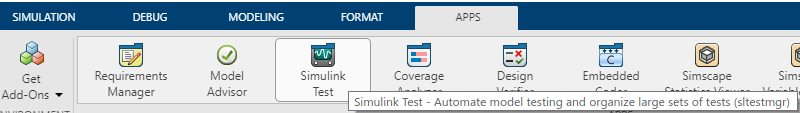

3) Click on the **Add Test Harness **button in the Simulink® Test™ app toolstrip. Make sure "CruiseControl" is shown in the text area for "Create Test Harness for". This will create a harness for the CruiseControl model and not the state chart. If you see "Compute target speed", change the slection to the CruiseControl model by clicking any empty area on the Simulink canvas.

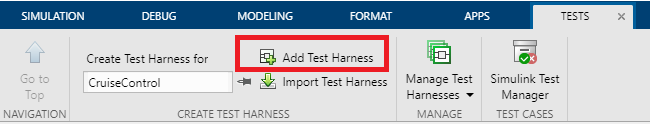

You will then see the **Create Test Harness** window.

4) Name the test harness **CruiseControl_Harness**.

5) Under Sources and Sinks, click on the input dropdown ("Inport" should be selected by default), and select **Test Sequence**.

6) Select "Save test harnesses externally". This will create a separate model file called **CruiseControl_Harness.slx** which we can use for testing. The test harness we will create will remain in sync with the design model, similar to how a [Model Reference](matlab:doc('Model Reference Basics')) works.

7) Save the harness in the Tests/Harnesses directory

8) Make sure "Open harness after creation" is selected.

9) Click OK.

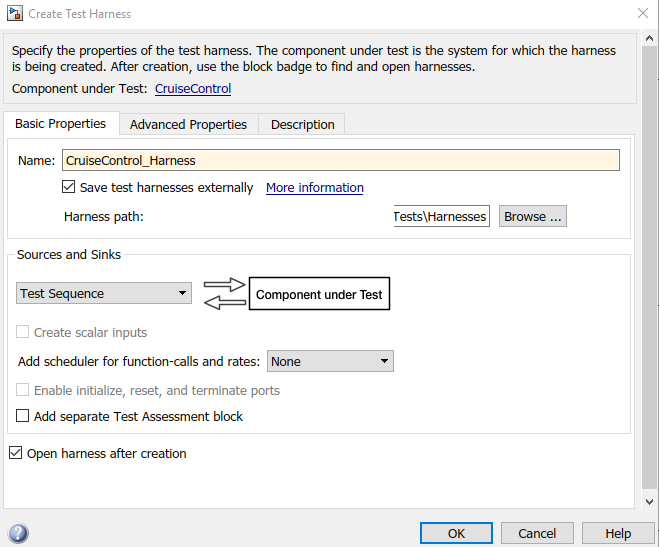

## Step 3: Author a Test Using a Test Sequence

A Test Sequence is a type of test input block available with Simulink® Test™. It allows you to write tests that follow a given set of steps that do not have to be time-based. For example, you can transition between test steps based on the value of an input signal. Both the test inputs and the pass/fail criteria can be defined in a Test Sequence block. One advantage of a Test Sequence over time-series based test vectors is that Test Sequences can be easier to maintain since they are based on response to simulation.

In this part of the example, we will only be defining the test inputs, as we will be using a Temporal Assessment to define the pass/fail criteria. For more information on the options available within a Test Sequence block, [**click here**](matlab:doc('Test Sequence'))**. **We will be using these features in Part 2 of the example.

For reference, here is the requirement you will be testing:

**"The cruise control system shall transition to disengaged from engaged within 0.25 seconds after a braking event has occurred."**

A simple test is to create a braking event while holding all other inputs constant.

Let's write this as a simple test sequence.

Here are the steps to take:

1) Open the Test Sequence Editor by double-clicking on the Test Sequence block in **CruiseControl_Harness.slx**

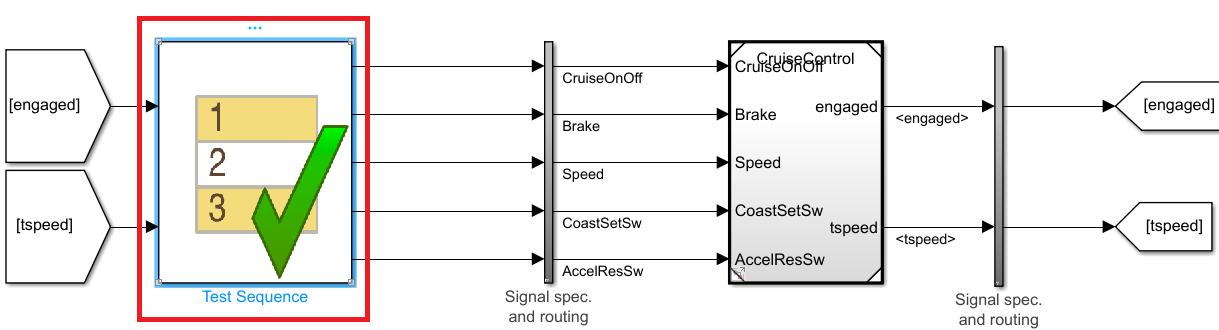

The first step in the Test Sequence is automatically created. It initializes the variables to zero.

Let's change the values for **CruiseOnOff** and **Speed**.

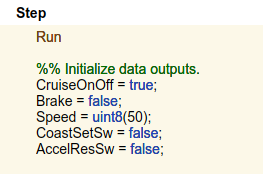

2) Add a new step to the Test Sequence by hovering over the bottom of the first step and clicking "Add step after"

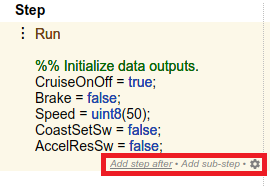

The new step will be called **step_1.**

3) Add a transition from the Run step. 

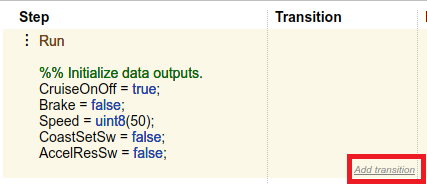

4) We will want to transition to step_1 after 2 seconds. This can be achieved using an "after" function.

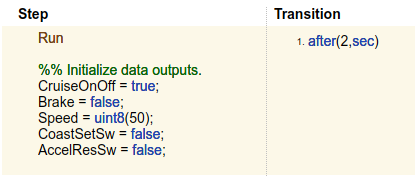

5) In step_1, set the Coast/Set Switch (CoastSetSw) to true. This will engage the cruise control.

6) Add one more step (step_2). Transition to step_2 after 2 seconds.

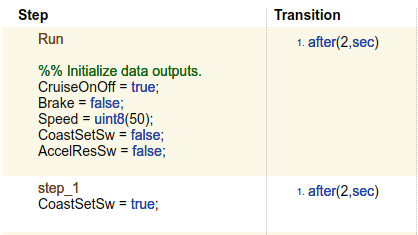

7) In step_2, set Brake to true.

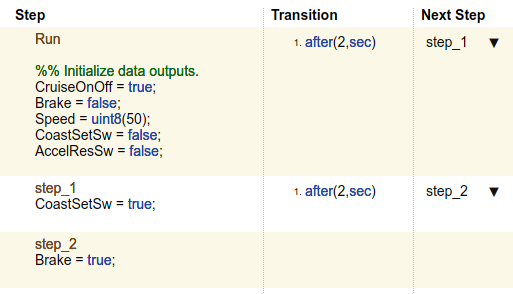

8) Log the **engaged** signal. This can be done by right clicking on the signal and selecting "Log Selected Signals".

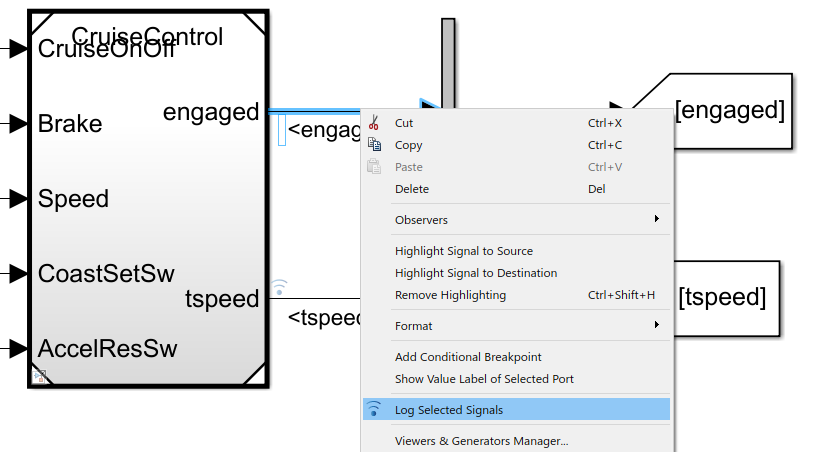

9) Simulate the test harness. Use the Simulation Data Inspector to verify that the engage state is entered and exited (make sure you log the engage signal).

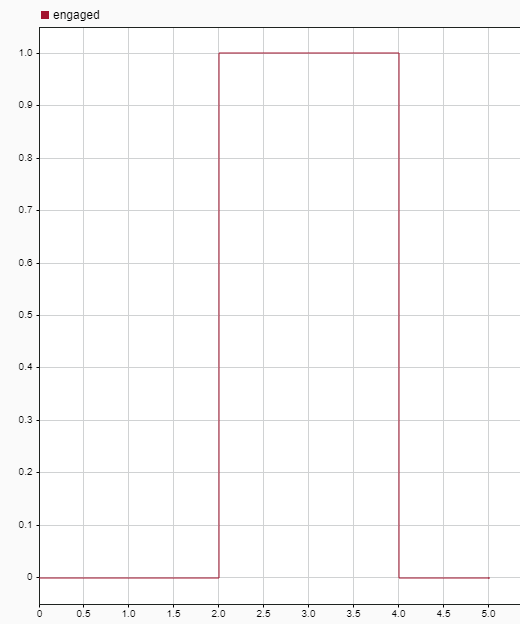

Congrats! You have created a test using a Test Sequence block. 

9) Save and close the harness model.

## Step 4: Create a Test Case Using the Test Manager in Simulink® Test™

Simulink® Test™ includes the Test Manager, which you can use to create and manage test cases.

A test case is a part of a test suite, which is a part of a test file. 

In this step, we will create a test case using the test harness we created in Step 3.

Here are the steps to take:

1) Open the Test Manager and create a test file.

You can open the Test Manager via the Simulink® Test™ app toolstrip by clicking on the "Simulink® Test™ Manager" button. Let's do this from the **CruiseControl.slx** model

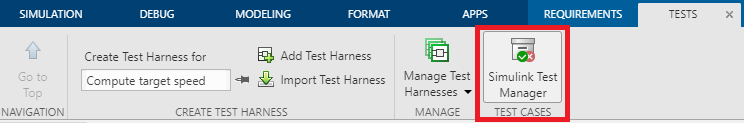

You can also open the Test Manager by running the following command:

sltestmgr

2) Create a new test file from the **CruiseControl.slx** model.

In the Test Manager, click **New -> Test File from Model**

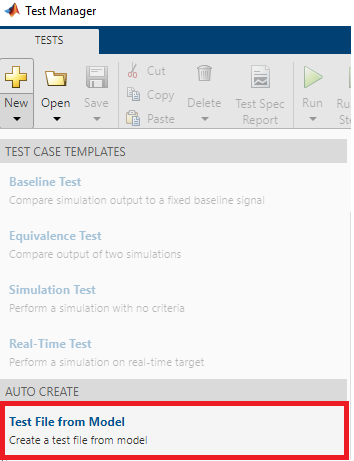

3) In the New Test File window, next to the Model text box, click on the icon to the ride labeled "Use current model".

In the Location field, name the test file **CruiseControlTest.mldatx. **Save it to the **Tests** folder.

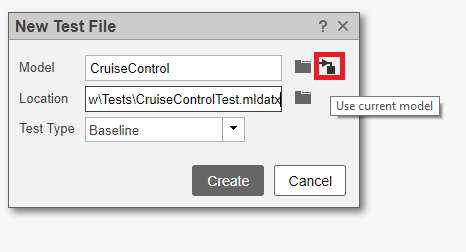

Keep the Test Type set to "Baseline"

4) Click **Create**

 The test case "CruiseControl_Harness"  will be created using the **CruiseControl_Harness.slx** model created earlier.

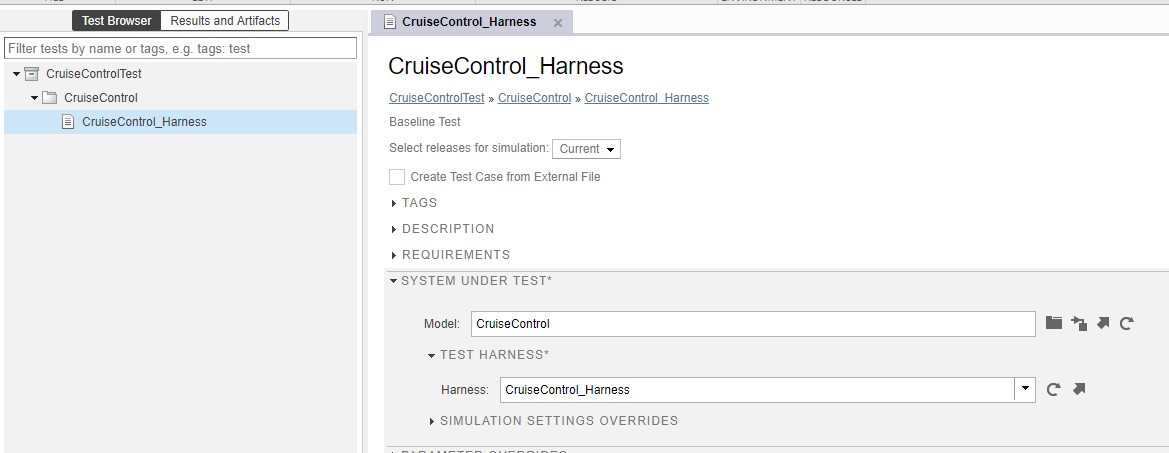

## Step 5: Create a Temporal Assessment for Pass/Fail Criteria

Next, we want to create pass/fail criteria for the test.

Let's use a Temporal Assessment to do this. A Temporal Assessment allows you to test timing-dependent logic using expressions that are readable and mathematically consistent. Since the requirement we want to test involves timing, we will use a temporal assement to define our pass/fail criteria.

Here are the steps to take:

1) Click on the **CruiseControl_Harness** test case (be sure the Test Browser tab is active)

2) Click on the drop-down to the **LOGICAL AND TEMPORAL ASSESSMENTS** menu.

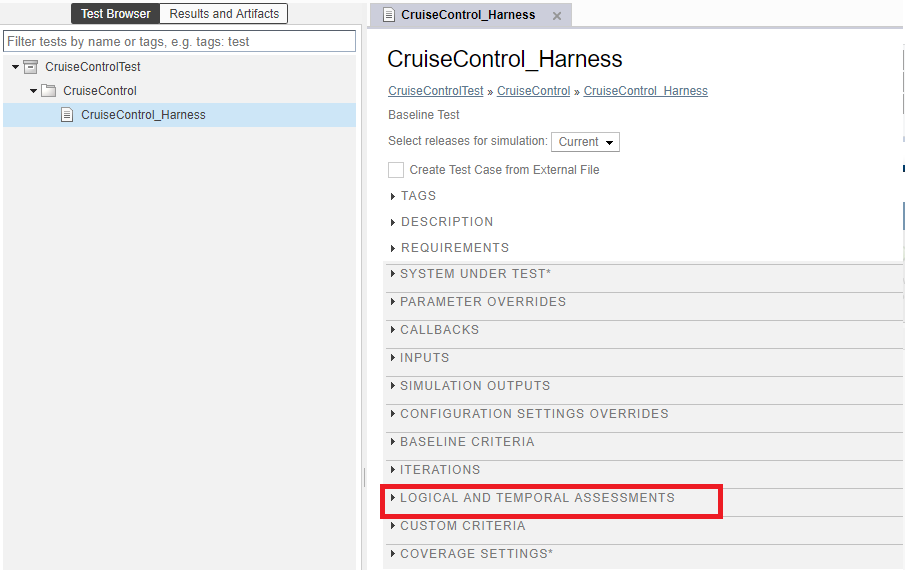

3) Click **Add Assessment**

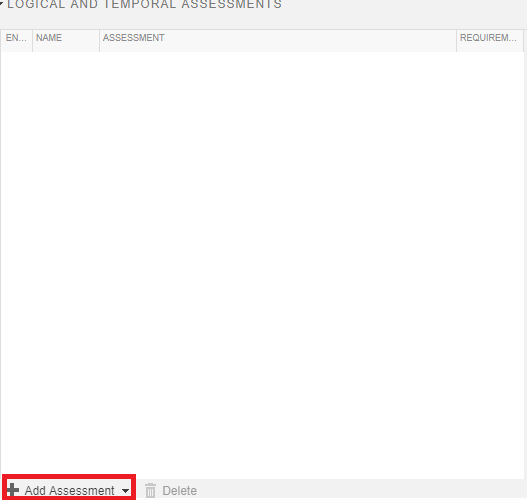

4) Select **Trigger-response**

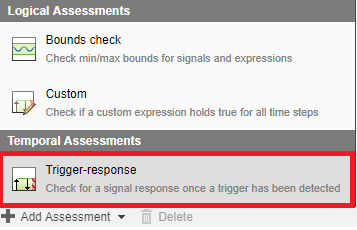

You can now define the expected behavior, which is for the **engaged **signal to go from TRUE to FALSE within 0.25 seconds of the **brake **signal becoming TRUE.

To do this:

1) Select the drop-down for "trigger" -> "becomes true"

2) Set condition: **brake**

3) Select the drop-down for "delay" -> "with a delay of at most"

4) Set max-time (sec): 0.25

5) Select the drop-down for "response" -> "must be true"

6) Set condition: **~engaged**

You then need to map the **brake **and **engaged **signals to the test harness model in the SYMBOLS section to the lower right.

To do this:

1) Select the icon to the right of the **brake **symbol in the SYMBOLS section -> "map to model element"

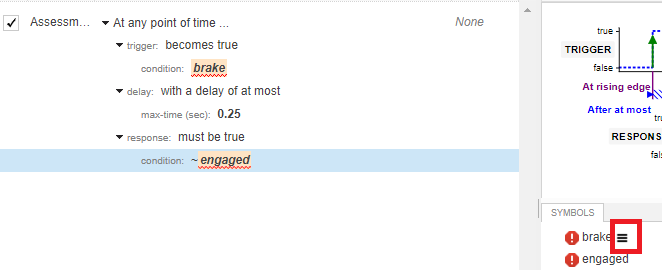

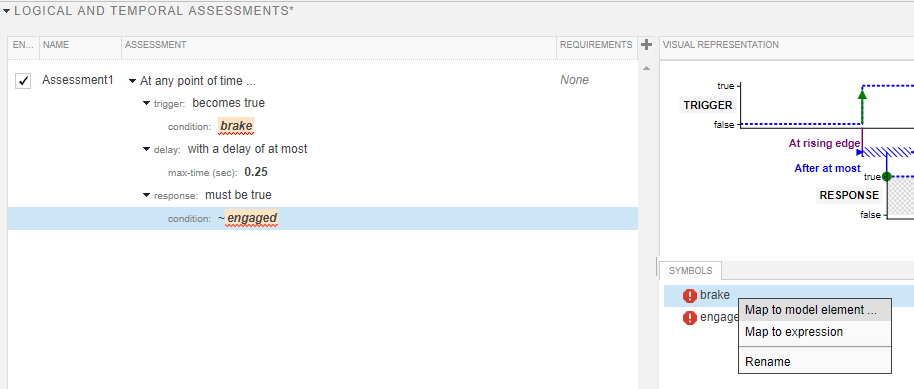

2) Within the model, select the signal line for **brake**. You should then see the "Connect" pop-up appear. 

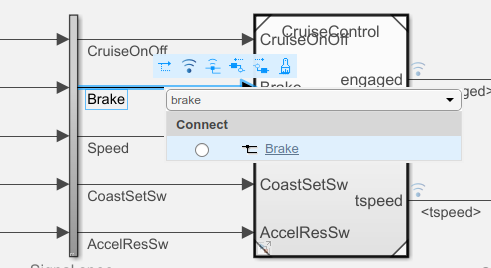

Click the radio button for "Brake"

3) Click on the line connecting to the engaged GoTo tag

4) Click on the drop-down to select **engaged**. This will map the selected signal to the engaged symbol in the Test Manager.

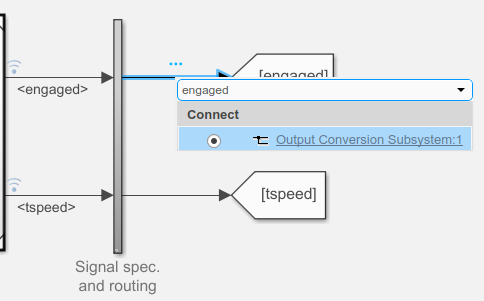

4) Click DONE

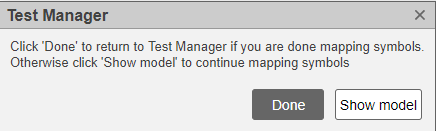

When you are done, the Temporal Assessment should look like this:

 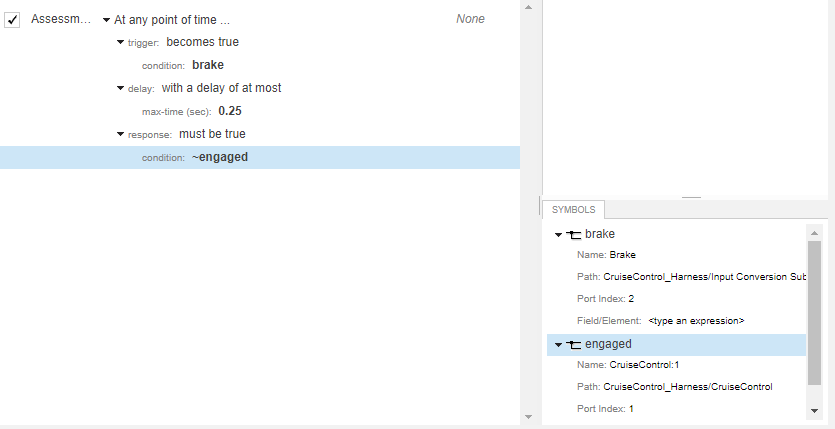

You can collapse the assessment into a more readable form:

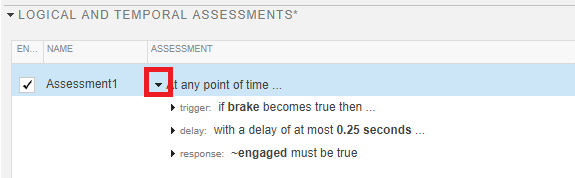

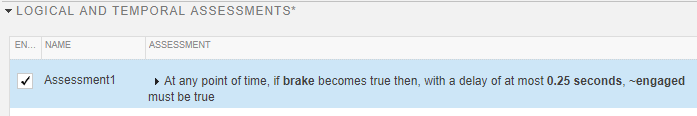

If you get stuck, [**click here**](matlab:openTestFileFinal) to open the final version of the Cruise Control test file. This will copy the solution files to your project and will let you continue to Step 7.

## Step 6: Execute the Test Case

Now that we have established our test inputs and pass/fail criteria, it's time to execute the test case to see if it passes.

To execute the test case, select it in the Test Manager and click the **Run** button in the toolstrip. You can also use the keyboard shortcut **CTRL + T** after selecting the test case.

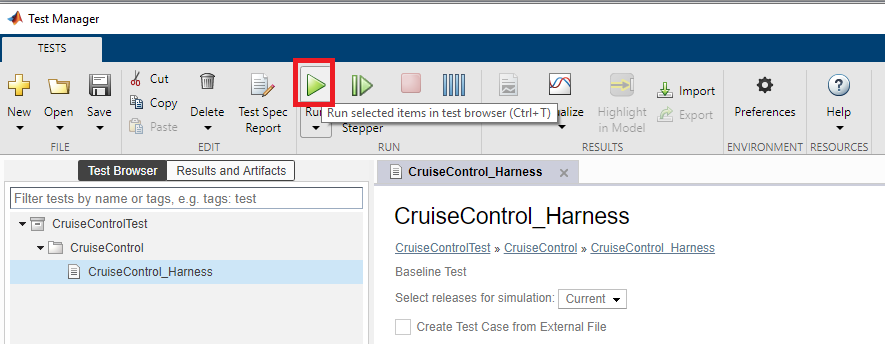

The Test Manager will automatically switch from the Test Browser tab to the Results and Artifacts tab, where you can see the progress of the test case execution.

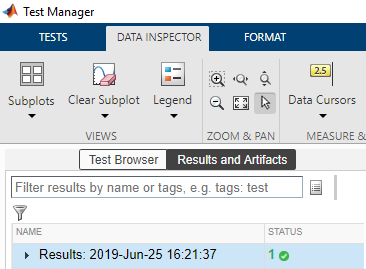

Congratulations! The test case passed.

## Step 7: Link the Test Case to the Requirement

Now that we have a working test case, let's make sure we link the test case to a requirement. This can all be done within Simulink® using Simulink® Test™ and Simulink® Requirements™.

By linking a test case to its associated requirement, we can later execute the test case directly from Simulink® Requirements™.

Here are the steps to take:

1) If you have closed them, re-open the **CruiseControl** requirements set and **CruiseControlTest** test file using the following code:

slreq.open('CruiseControl');
sltest.testmanager.load('CruiseControlTest.mldatx');
sltest.testmanager.view

2) In the Test Manager, click on the **CruiseControl_Harness** test case

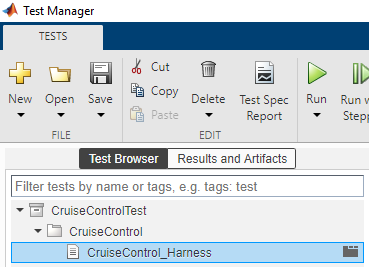

3) In the Requirements Editor, right click on the requirement with ID #34 and select **Link from Selected Test Case**

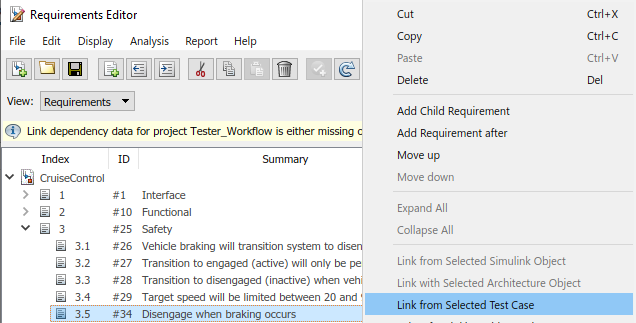

Notice in the Links section of the Requirements Editor that there is now a "Verified by" link for this requirement.

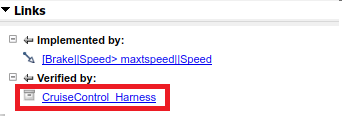

Congrats! You have successfully created a new test case using a Test Sequence and a Temporal Assessment, as well as linked the test case to its relevant requirement.

Be sure to take the following steps before moving on to Part 2:

- Close all open models

- Close the Requirements Editor window

- Close the CruiseControl_Test Test File in the Test Manager window

# **Part 2: Run a Test Suite and Resolve Missing Model Test Coverage**

In Part 2 of the example, we will be running a full suite of tests to make sure we have fully tested the design.

The goals for this part are to learn how to:

- execute a test suite using Simulink® Test™

- measure test coverage

- generate tests to analyze missing test coverage

- resolve missing test coverage

Model test coverage, or "model coverage," is a measure of how much of your design has been tested through simulation. Having full model coverage ensures that you have accounted for all behavior in your model. Missing model coverage may be the result of dead logic, incomplete testing, unexpected functionality, or incomplete/missing requirements.

In addition to Simulink® Requirements™ and Simulink® Test™, which you used in Part 1, you will be using the following products in Part 2:

**Simulink® Coverage™ **is used to measure test coverage for Simulink models and generated code.

**Simulink® Design Verifier™** is used to detect design errors, generate tests to achieve test coverage goals, and formally verify requirements using static analysis.

### Step 1: Open Test Suite in Test Manager

You will be running a pre-created test suite within Simulink® Test™. This test suite contains several test cases, each of which has been linked to its relevant requirements.

A best practice is to limit the scope of a test to its related requirements. This is done in order to make it easier to analyze why a test failed. A test that addresses many requirements may seem more efficient, but can become burdensome to troubleshoot when the test fails. In addition, as the requirements and design mature, regression testing can be made easier by having more narrowly scoped tests. In short: try to maintain a 1:1 relationship between requirements and tests whenever possible.

With this in mind, most of the tests in the pre-created test suite were written to test a single requirement.

Run the following code to open the test file in the Test Manager:

sltest.testmanager.load('CruiseControl_TestSuite.mldatx');
sltest.testmanager.view

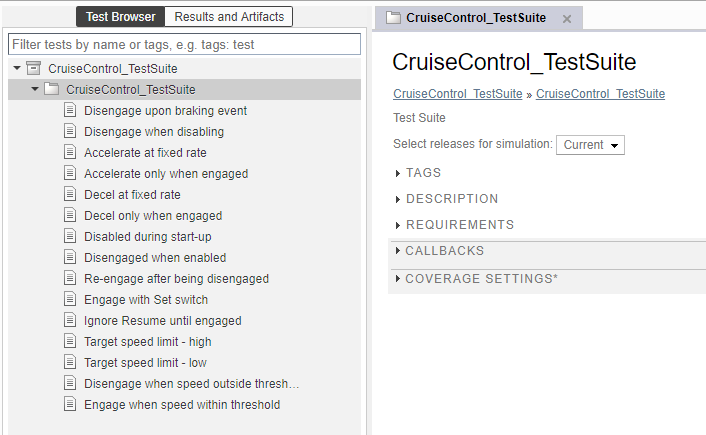

The test suite consists of several test cases, each of which tests a single requirement.

### Step 2: Enable Coverage Collection

We now need to enable model coverage collection for the test suite. This is known as "aggregated coverage", because model coverage is collected for each test case and then aggregated across all test cases in the test suite.

Model coverage is collected by **Simulink® Coverage™**, which is a separate product from Simulink® Test™.

To enable model coverage collection:

1) Click on the **CruiseControl_TestSuite** test suite in the Test Browser in the Test Manager

2) Open the COVERAGE SETTINGS section

3) Select "Record coverage for system under test"

In the COVERAGE METRICS section, the following metrics are already selected: Decision, Condition, and MCDC. [**Click here**](matlab:doc('Types of Model Coverage')) to learn more about these coverage metrics.

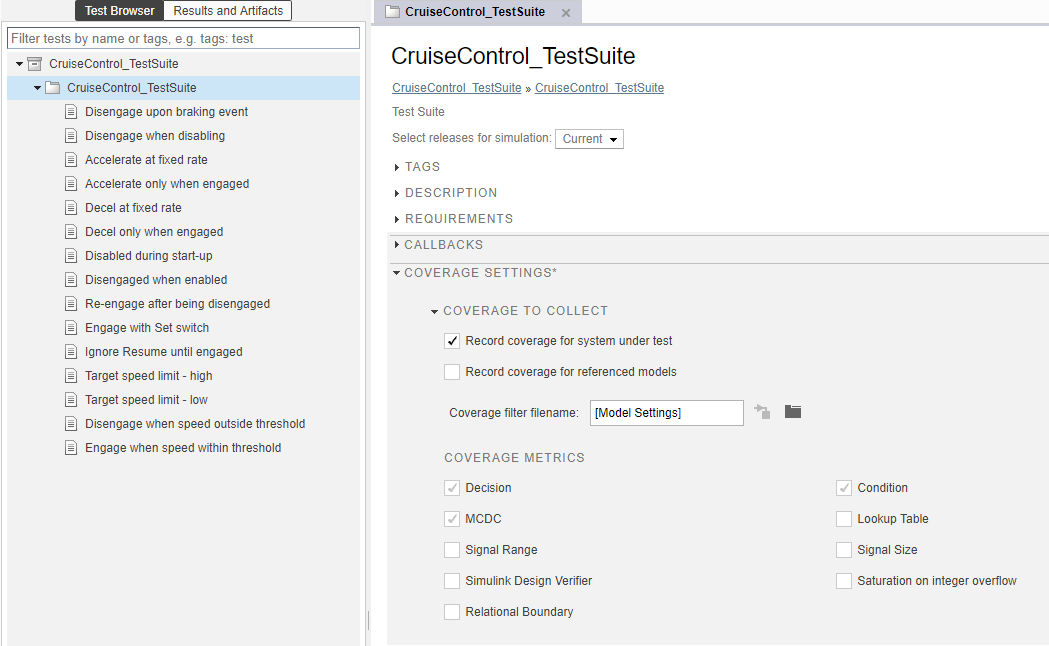

### Step 3: Execute Test Suite

To execute the test suite:

1) Select the test suite **CruiseControl_TestSuite** in the Test Browser 

2) Click **Run** in the toolstrip or by using the keyboard shortcut **CTRL + T**

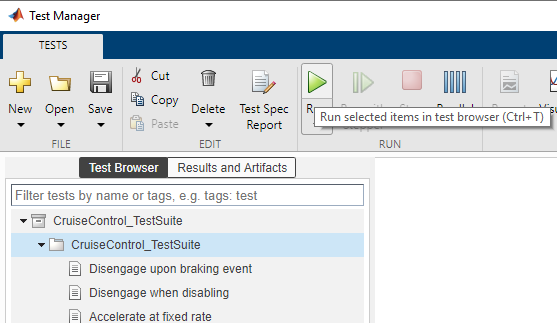

The Test Manager will automatically switch to the **Results and Artifacts** tab to show the test execution progress. This test suite has 15 test cases.

### Step 4: View Model Coverage Results

To view model coverage results, click on the most recent test run in the **Results and Artifacts** tab in the Test Manager, then look under AGGREGATED COVERAGE RESULTS.

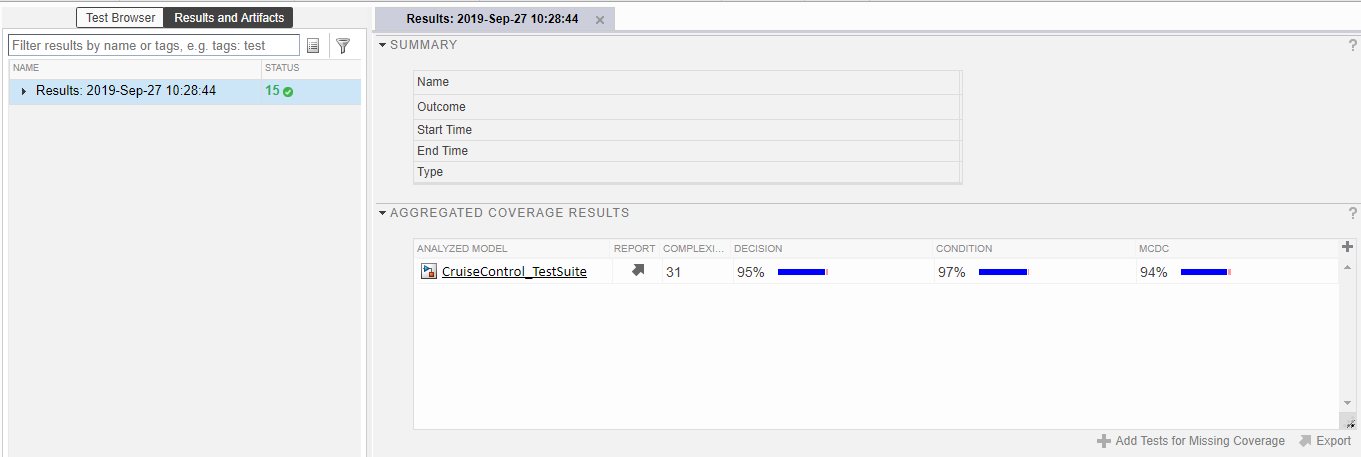

This section shows you how much of the design was tested by the full test suite.

It looks like you are missing some Decision, Condition, and MCDC coverage.

Let's take a look at the missing coverage on the model itself.

- Click on the link to the **CruiseControl_TestSuite** model.

The model will open up with model coverage highlighting enabled.

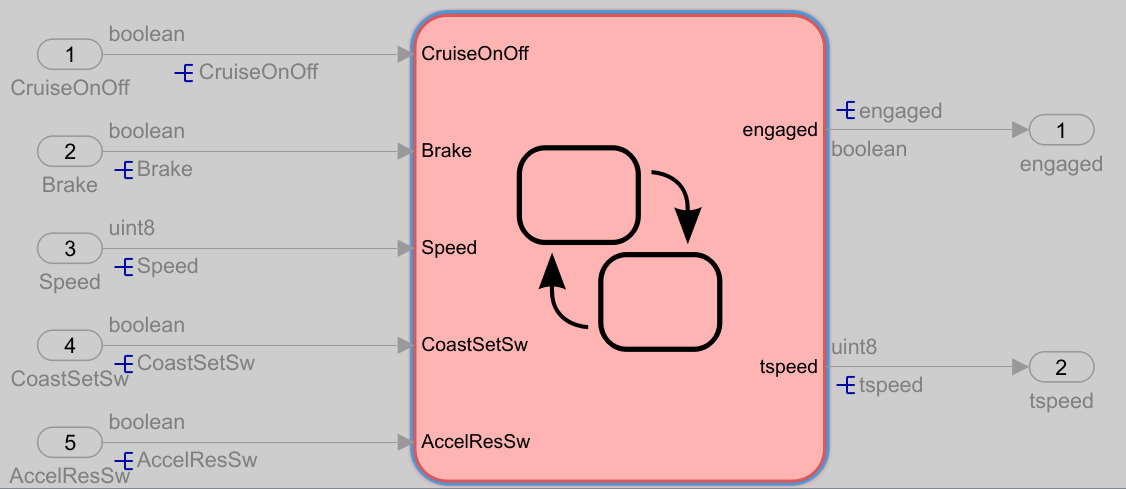

Red highlighting signifies incomplete coverage. Let's open the state chart.

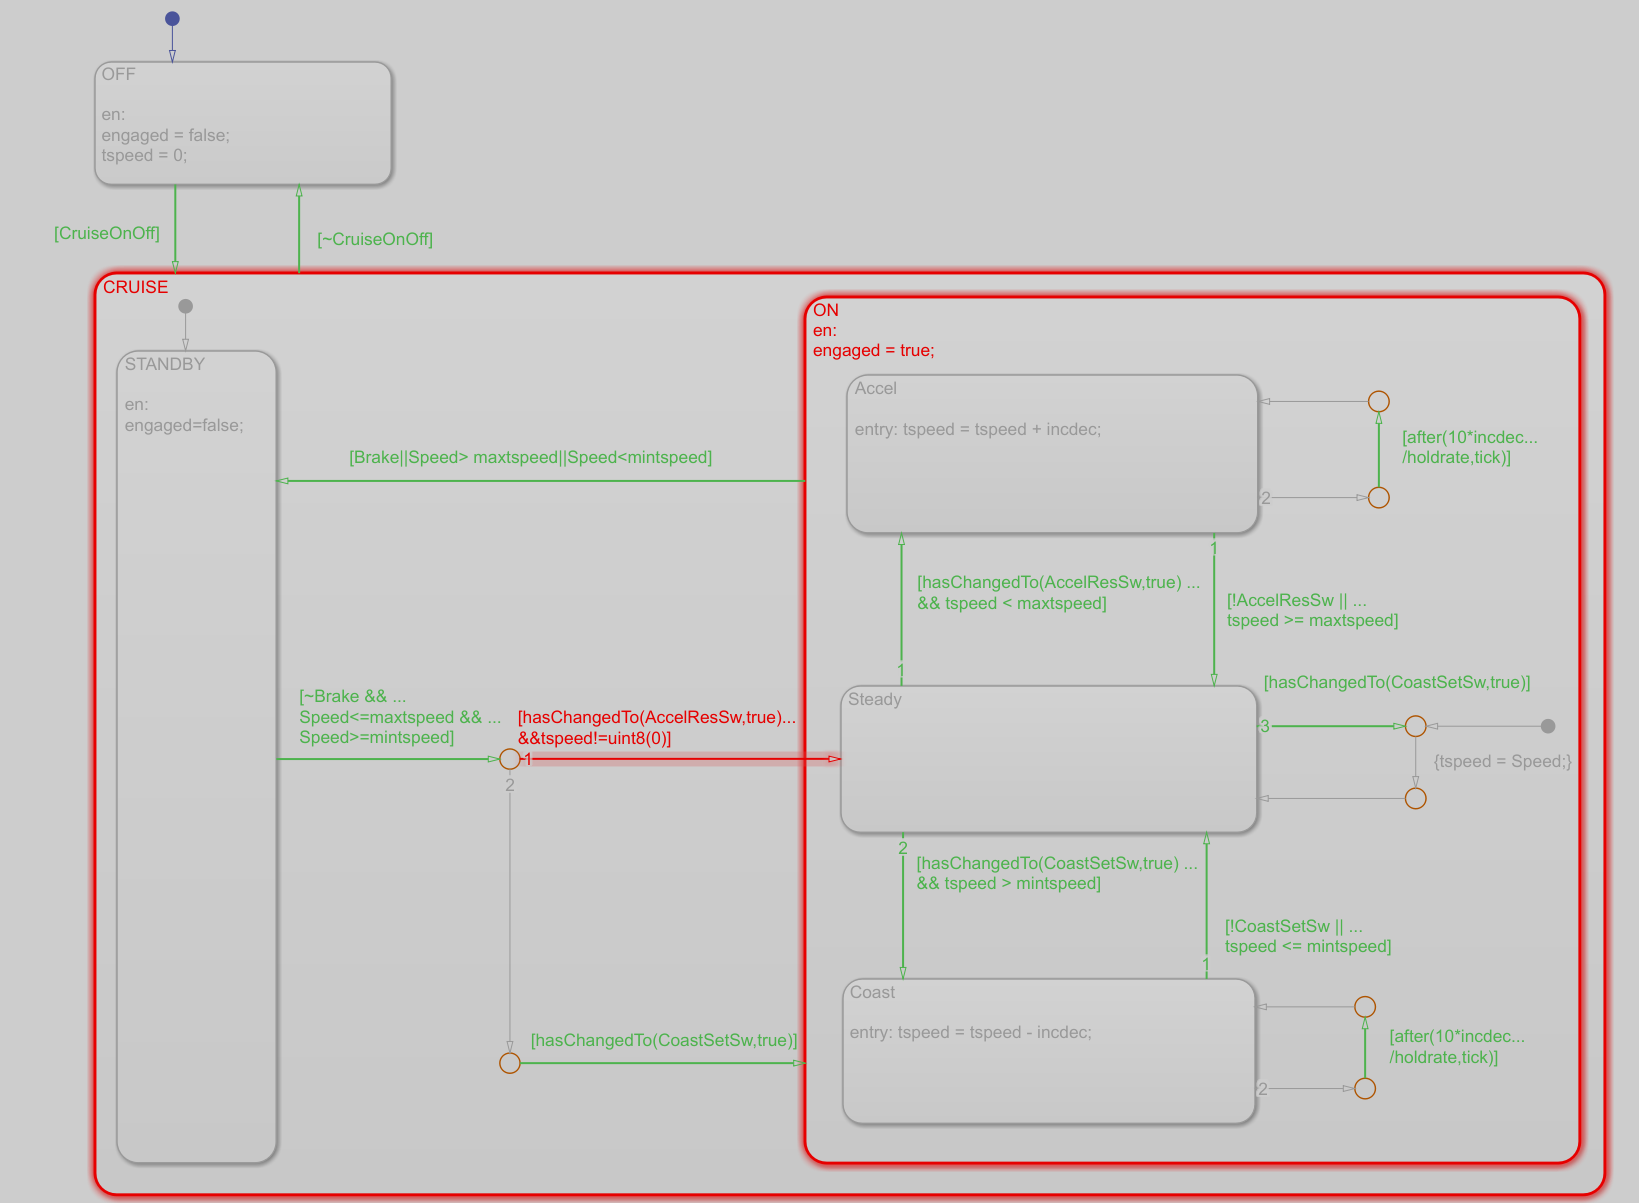

It looks like we are missing model coverage in a few spots. Let's take a closer look at one of them.

2. Hover over the CRUISE state name:  **CRUISE**

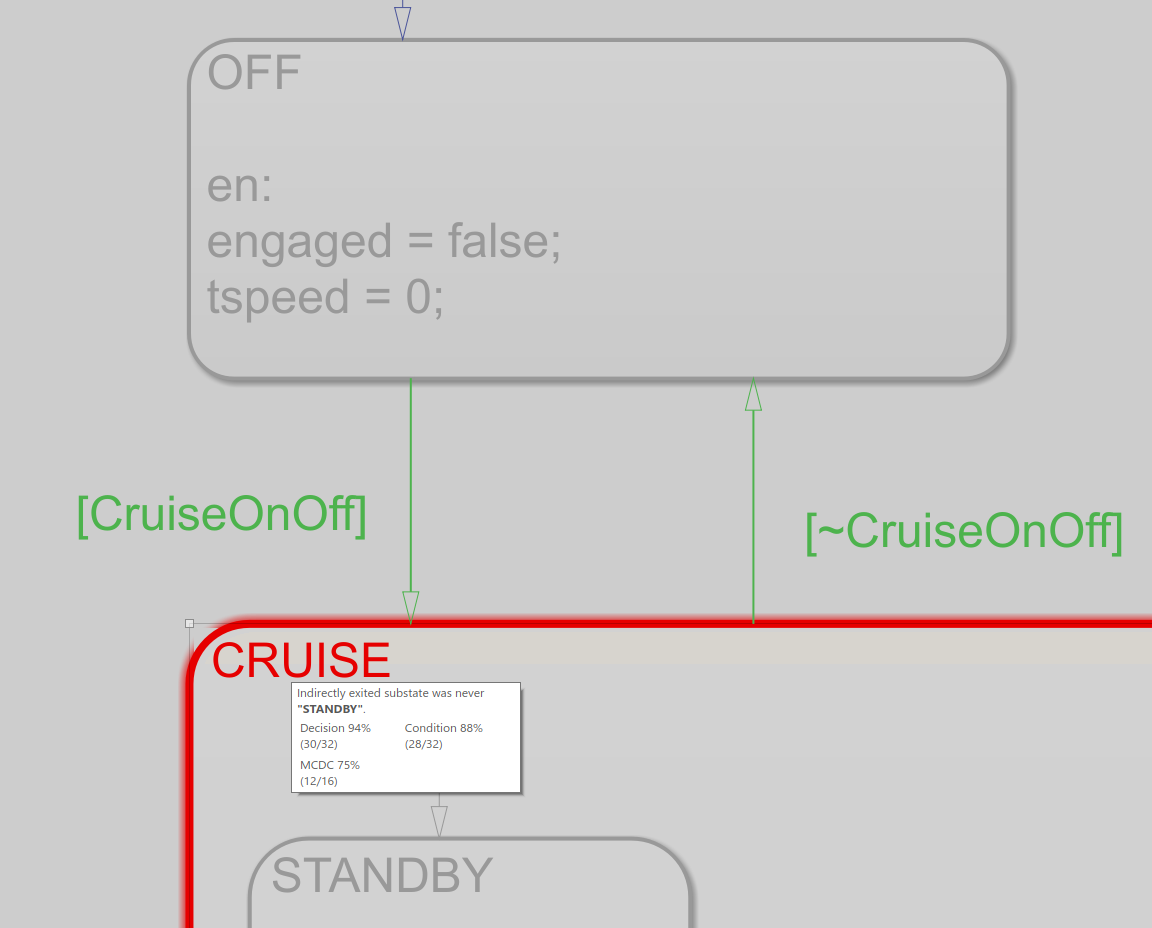

It looks like the CRUISE state was never exited from the STANDY substate.

You can verify this by opening the test harness used to create the test case by running the following code (the Test Sequence block will open.):

load_system('CruiseControl_TestSuite_Harness_Disengage_when_disabling')
open_system('CruiseControl_TestSuite_Harness_Disengage_when_disabling/Test Sequence')

The test case entered the ON state before existing CRUISE.

This is a fairly simple fix: we just need to add a step in the test case to exit the CRUISE state when in the STANDBY state.

The expected result will be that engaged = FALSE before and after exiting the CRUISE state.

In the Test Sequence block, add the following four steps:

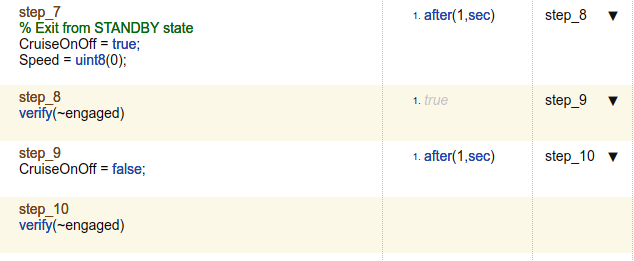

If you get stuck, open the following test harness:

load_system('CruiseControl_TestSuite_Harness_Disengage_when_disabling2')
open_system('CruiseControl_TestSuite_Harness_Disengage_when_disabling2/Test Sequence')

We have addressed one element of our design that had incomplete model coverage.

Let's look at another place in our model with missing model coverage.

3. Take a look at the transition into the **ON **state

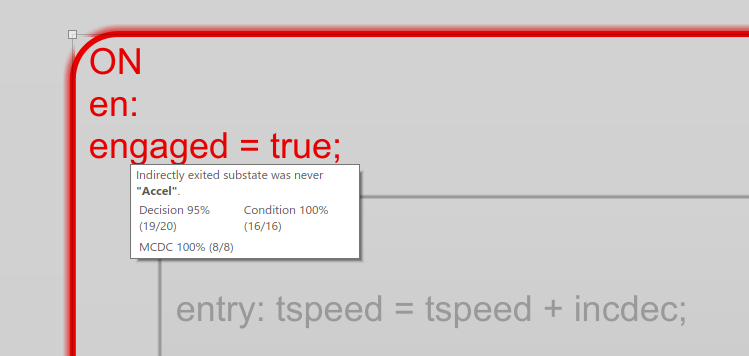

We are missing some Decision coverage for this state. It looks like we don't have a test that exits the ON state from the Accel state.

This would involve creating a test that steps through a few states and substates in the model. Is this achievable? Is there a way to automate this to save time?

Let's try generating tests automatically to answer these questions.

### Step 5: Generate Tests to Analyze Missing Model Coverage

There are many causes for missing model coverage, including dead logic, incomplete requirements-based tests, or missing or incomplete requirements.

One way to analyze missing model coverage is to generate test vectors, which can help you understand what the inputs would need to be in order to reach a given point in your design. These generated test vectors can also be used to supplement existing requirements-based tests.

Simulink® Design Verifier™ can be used to automatically generate test vectors to analyze missing model coverage.

The two most important questions this workflow answers are:

1) Is my design fully testable? In other words, is there dead logic? If a test cannot be generated to reach certain parts of your design, there might be dead logic in the design.

2) If my design is fully testable, what would a test cases look like? You can think of a test case as a "language" that can help you understand why you are missing test coverage in your requirements-based tests.

You can launch Simulink® Design Verifier™ directly from Simulink® Test™.

1) In the Results and Artifacts view in the Test Manager, click on the most recent test run

2) Under the AGGREGATED COVERAGE RESULTS section, click in the whitespace of the row with the name of the model

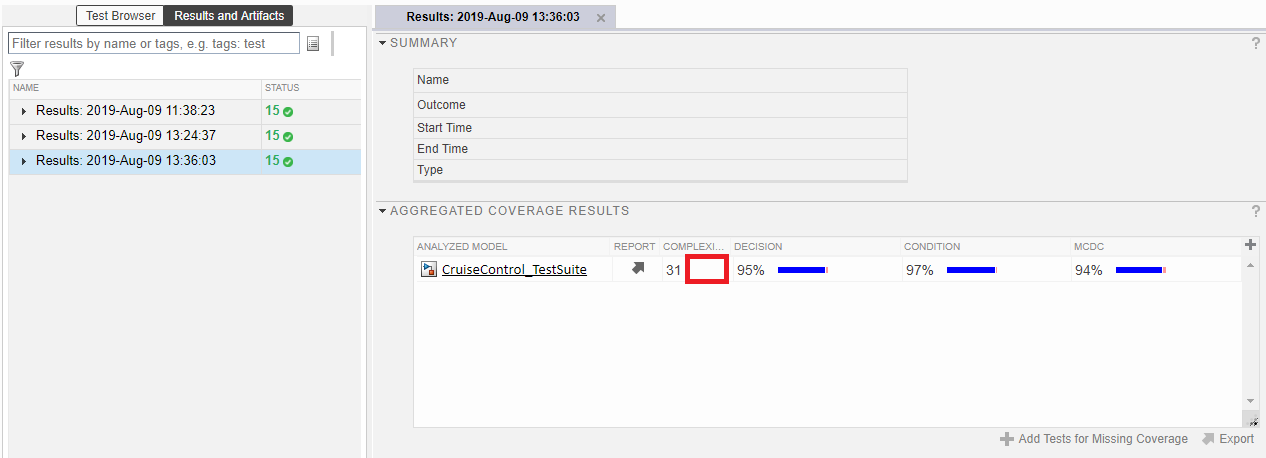

3) Click "Add Tests for Missing Coverage"

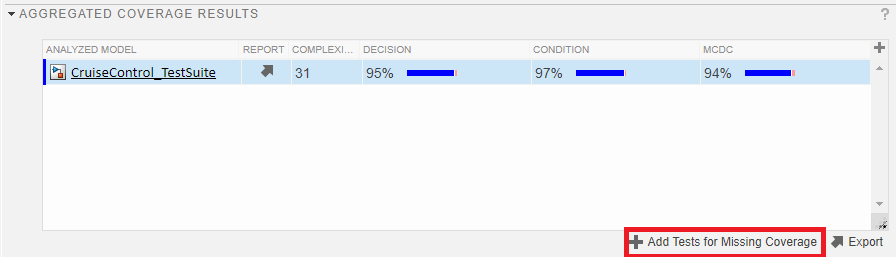

In the "Add Tests for Missing Coverage" pop-up, choose the following options:

1) **Harness**: <Create a new harness>

2) **Source**: Signal Builder

3) **Test Case**: <Create a new test case>

4) **Test Type**: Simulation Test

5) **Test File**: CruiseControl_TestSuite

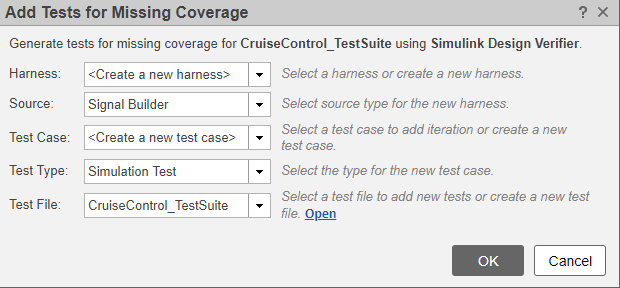

6) Click OK

We want to create a Simulation Test because there are no expected results for the automatically generated tests. In a typical requirements-based testing workflow, we would create Baseline Tests. However, we want to use the automatically generated tests to understand the missing coverage. Therefore, there is no need for a Baseline Test, which has expected results, to be created.

Simulink® Design Verifier™ is then automatically launched with these settings. It will take into account the coverage achieved with the existing test cases, and will try to generate tests to fill in the remaining coverage.

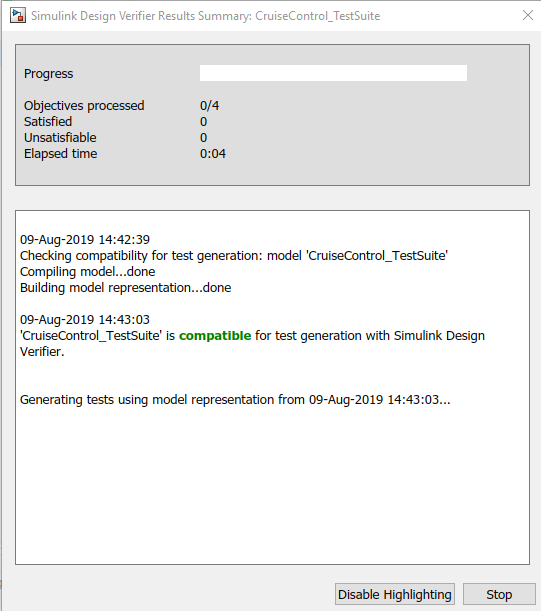

Once Simulink® Design Verifier™ has finished generating tests, the new test case will appear in the Test Manager:

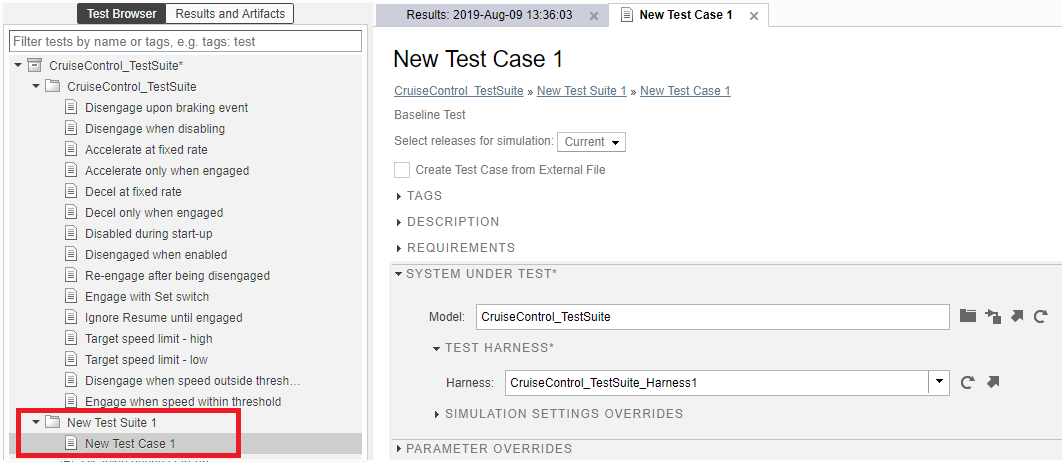

Let's move this new test case into our existing test suite. You can do this by right clicking on the test case and selecting Cut, then Paste into the CruiseControl_TestSuite

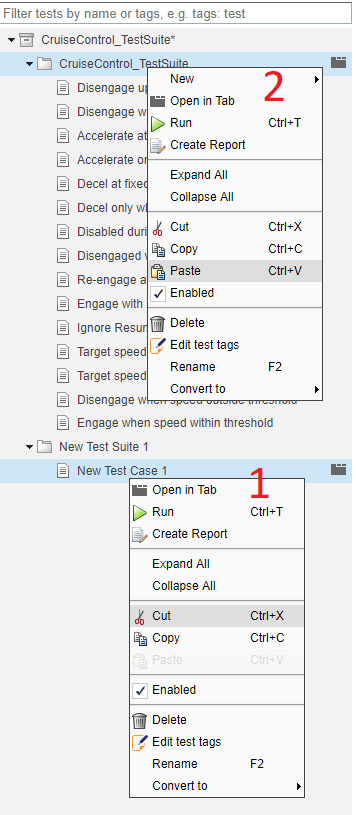

Let's run **CruiseControl_TestSuite** with the new test case.

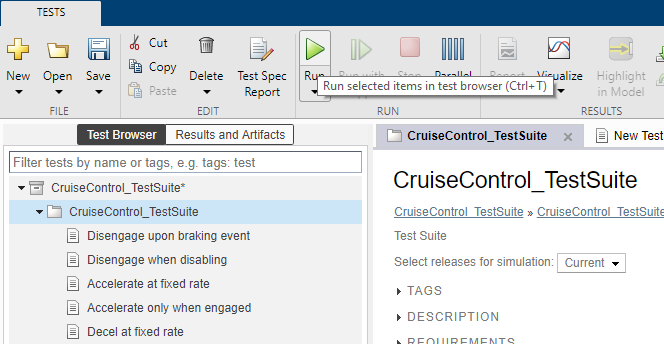

Here are the results:

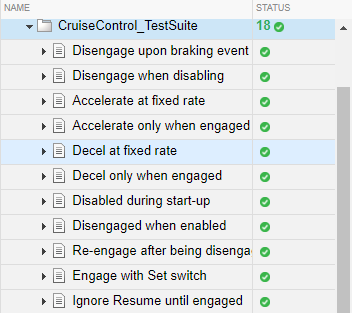

Notice that the summary of the test suite shows 18 tests have passed. This is expected, as we created Simulation Tests for the automatically generated tests. There are no expected results for these new tests.

Let's generate a coverage report. This will help us understand which test case addressed each of the missing coverage objectives.

We can generate a coverage report by clicking on the arrow icon in the Report column in the AGGREGATED COVERAGE RESULTS section.

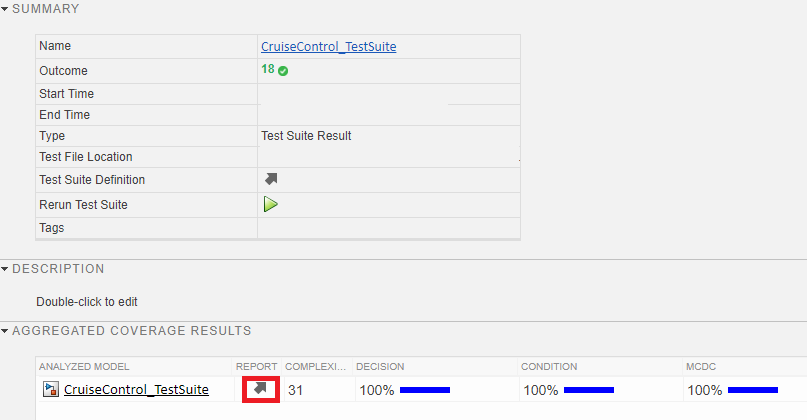

You will then see an HTML report showing the aggregated coverage.

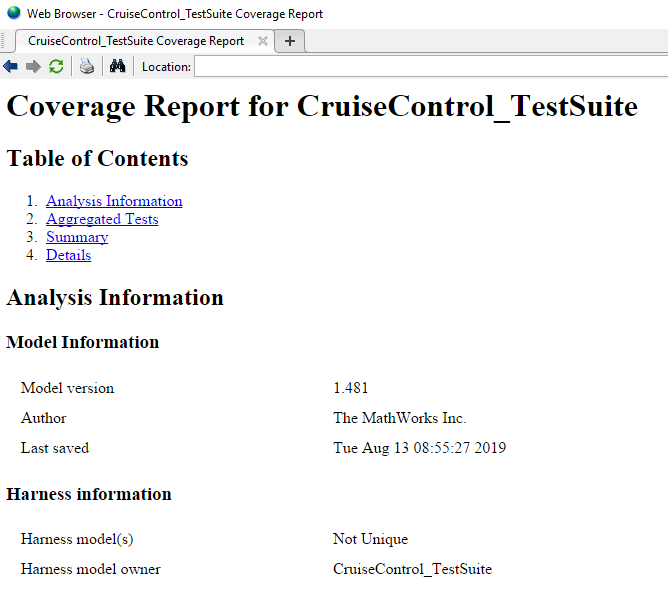

You can navigate to any model element in the Summary section.

In the Summary section, let's navigate to the **SF: ON** state.

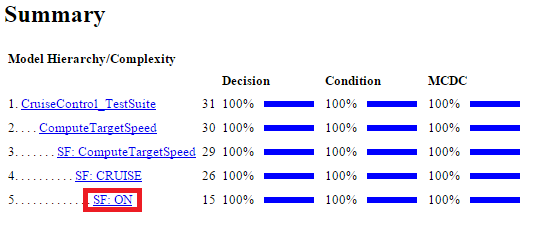

Here are the coverage results for the ON state:

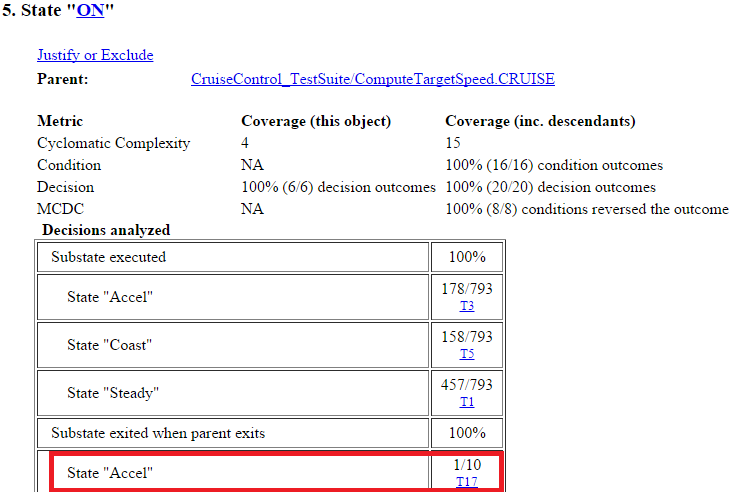

Recall that we are looking for a test case that would exit the ON state from the Accel substate. It looks like Test Case T17 did that. This was one of the automatically generated tests. 

Let's click on the hyperlink "T17".

This will bring us up the list of the tests at the top of the report.

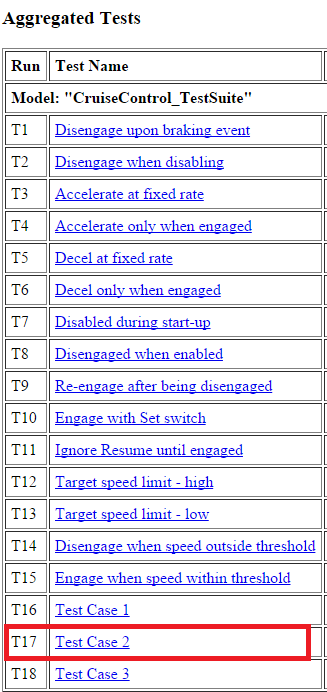

It looks like T17 is Test Case 2, which was an automatically generated test.

Let's click on the hyperlink "Test Case 2" to see the test case in Simulink® Test™.

Let's also rename the automatically generated test case "New Test Case 1" to "Generated tests for coverage" for easier reference in the future.

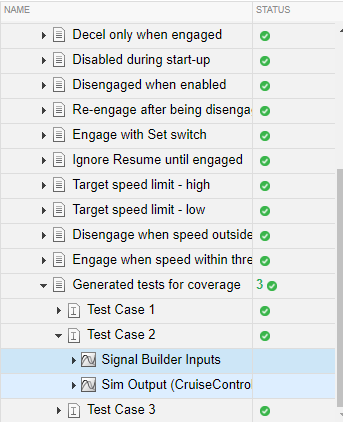

Let's visualize the test case. This can be done using the Visualize button in the toolstrip. Select "Show Simulation Output Plots".

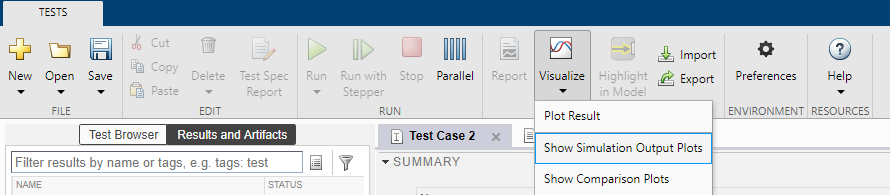

We can view the inputs by adding them via the Signal Builder Inputs dropdown. We can also add subplots using the Subplots button in the Toolstrip. We can also use the Zoom in Time button to view the beginning of the test case.

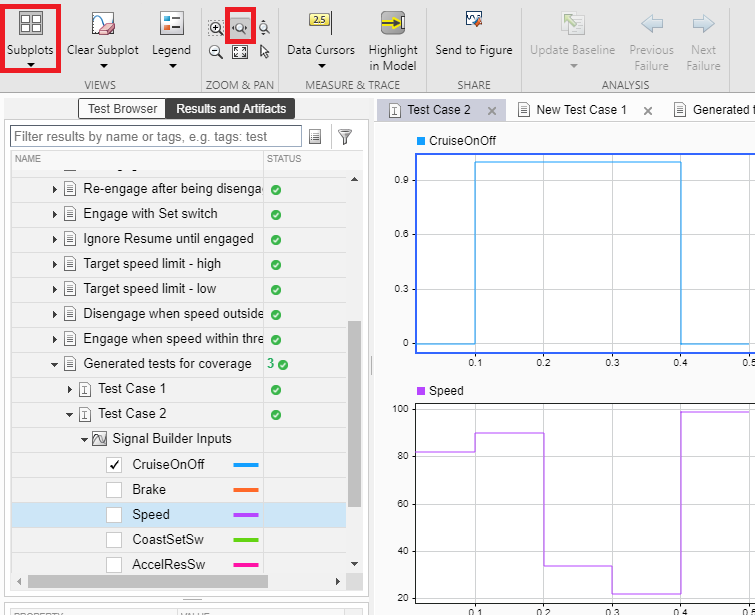

By doing this, we can see how we would have achieved missing coverage.

The next step is to determine whether or not we should:

1) Write a new requirement

2) Modify an existing requirement

3) Append to or modify an existing test

4) Justify the missing coverage

In this case, the simplest option is #3: Append to or modify an existing test

In this case, we can simply append some additional steps to the **Disengage upon braking event** test case.

You can do this by opening the test harness using the arrow button in the Test Manager.

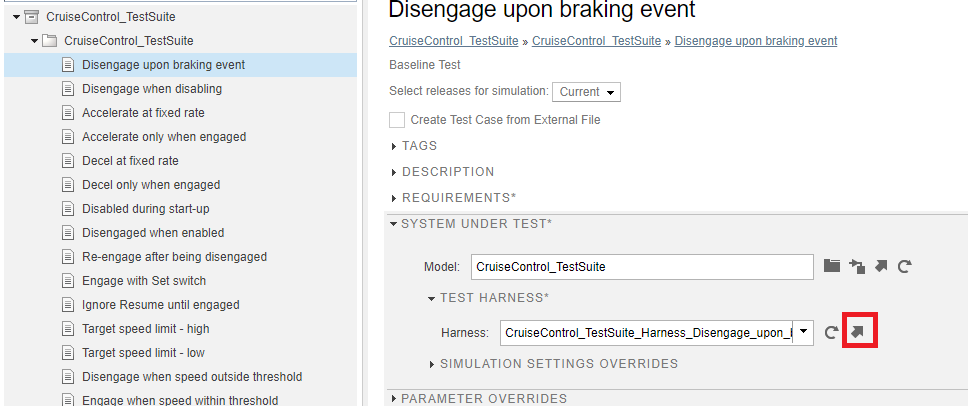

Try this yourself. If you get stuck, run this code to open an example solution:

load_system('CruiseControl_TestSuite_Harness_Disengage_upon_braking2')
open_system('CruiseControl_TestSuite_Harness_Disengage_upon_braking2/Test Sequence')

### **Step 6: Associating Tests, Coverage, and Requirements for Better Testing**

You can use the model coverage report to view the relationships between tests, coverage, and requirements.

This is an important workflow, and is required in certification standards such as DO-178 and ISO 26262. It is a recommended practice.

Besides ensuring that your tests pass, you need to make sure that the tests for a given requirement are covering the implementation of that requirement.

Let's go through two examples to illustrate an ideal testing scenario and a less-than-ideal testing scenario.

Here is an example from the **"ON" **state section in the coverage report:

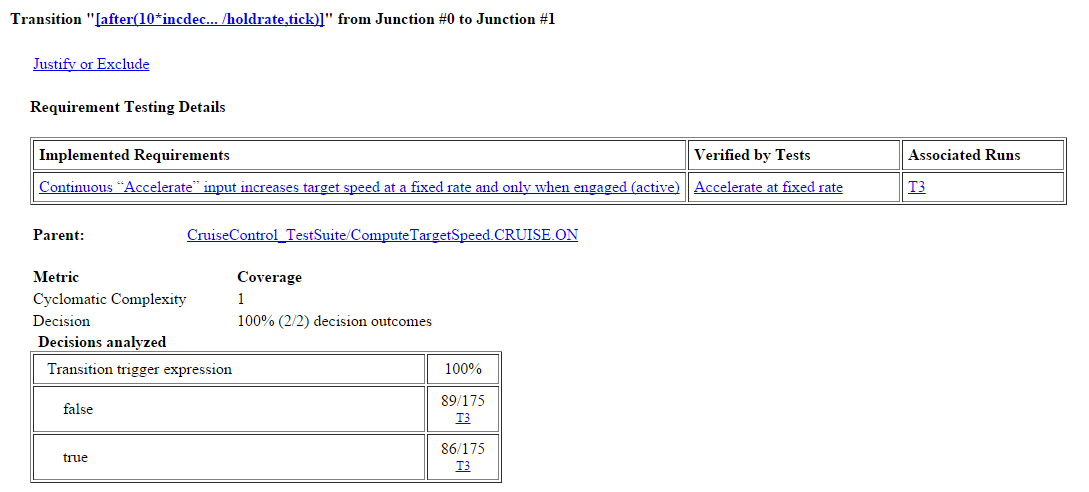

Here is how to interpret the results:

1: This transition was linked to one requirement.

2: The requirement was verified by one test, which is labeled "T3". This is determined through traceability links using Simulink Requirements and Simulink Test.

3: Using the coverage results, it looks like the test T3 achieved 100% Decision coverage.

4: We can therefore conclude that the correct test (T3) achieved full coverage for this transition. We don't need to write any additional tests or link to additional requirements.

Is this always the case?

Let's take a look at another transition. In the coverage report, this can be found just below the previously mentioned model element:

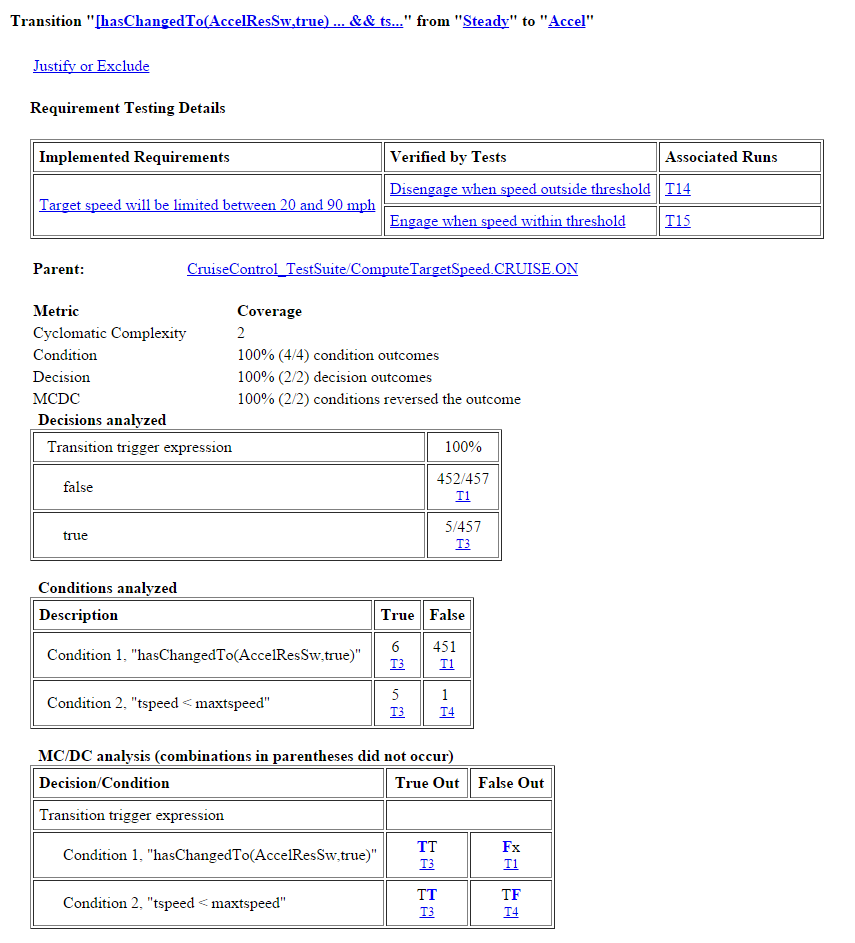

It looks like we have a problem. Here is how to interpret these results:

1: This transition was linked to a single requirement.

2: The requirement is verified by two tests, labeled T14 and T15.

3: In the coverage results, it looks like we achieved 100% coverage.

4: **The problem**: The coverage was achieved by tests T1, T3, and T4, **not **T14 and T15. This is called "**incidental coverage**", as the tests that achieved the coverage are not the same tests that are associated with the linked requirements. Complete coverage should be achieved by T14 and T15, which are the tests linked to the requirement.

We should have received 100% of our coverage from tests T14 and T15. The next step would be to look at these tests as well as tests T1, T3, and T4 to determine whether or not we should change the requirements linking or re-write the tests.

This is a fairly common experience during requirements-based testing. It is important to ensure that your requirements-based tests are covering the model elements associated with the correct requirements. Not doing so can lead to cases where a model element is covered in an unexpected way.

**Congratulations!** You have successfully tested the model and ensured complete test coverage. Simulink® Design Verifier™ includes several other features, such as design error detection and property proving. Be sure to check out these other features.

# Summary

In this example workflow, we:

- created a test harness

- authored a test case using a Test Sequence block

- created and executed test cases

- analyzed missing coverage by generating tests

You are now one step closer to setting foot in the fancy new lab!